Лабораторна робота №3

Виконала: Щербина Софія ФФ-41

Варіант №13

Завдання:

1) Отримати з файлу mri.mat зріз черепної коробки людини та збільшити отримане зображення вдвічі.

load mri;
D = squeeze(D);
img = D(:,:,13); 
img_big = imresize(img, 2, 'bicubic');

2) Застосувати до отриманого збільшеного зображення різні способи підвищення яскравості (histeq, imadjust, adapthisteq).

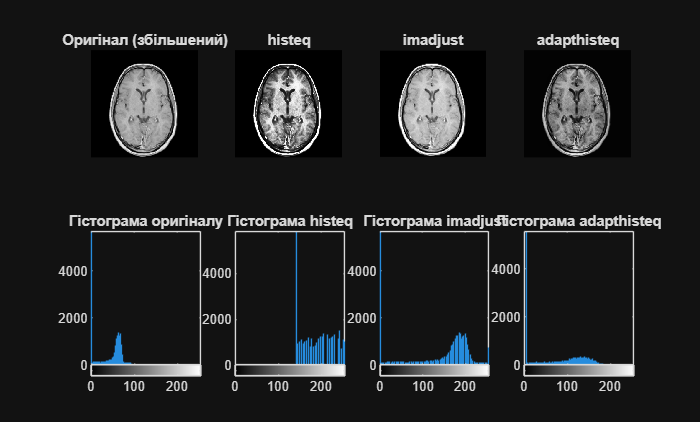

colormap(gray);
figure('Name', 'Корекція яскравості');
subplot(2,4,1); imshow(img_big, []); title('Оригінал (збільшений)');
subplot(2,4,5); imhist(img_big); title('Гістограма оригіналу');

img_histeq = histeq(img_big);
subplot(2,4,2); imshow(img_histeq, []); title('histeq');
subplot(2,4,6); imhist(img_histeq); title('Гістограма histeq');

img_adjust = imadjust(img_big);
subplot(2,4,3); imshow(img_adjust, []); title('imadjust');
subplot(2,4,7); imhist(img_adjust); title('Гістограма imadjust');

img_adapt = adapthisteq(img_big, 'ClipLimit', 0.02);
subplot(2,4,4); imshow(img_adapt, []); title('adapthisteq');
subplot(2,4,8); imhist(img_adapt); title('Гістограма adapthisteq');




best_img = img_adapt; 

3) Провести обробку найкращого із зображень, отриманих у п.2), підібравши оптимальну комбінацію цифрових фільтрів та вивести його у псевдокольорі. Для наочності порівняння в різні підвікна одного графічного вікна виводити отримані зображення та їхні гістограми з пояснювальними надписами.

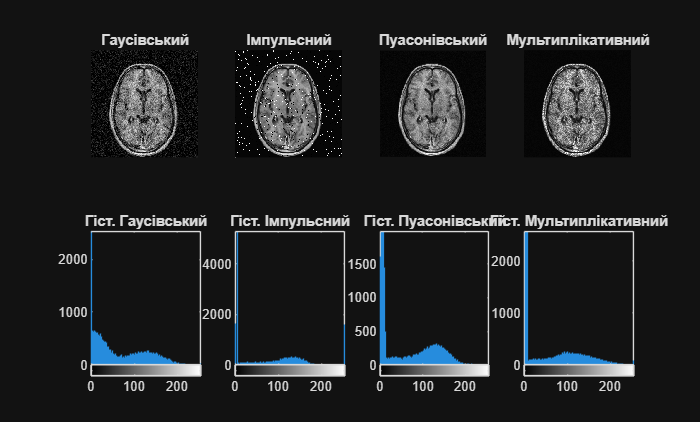

figure('Name', 'Аналіз шумів');
noises = {'gaussian', 'salt & pepper', 'poisson', 'speckle'};
titles = {'Гаусівський', 'Імпульсний', 'Пуасонівський', 'Мультиплікативний'};

for i = 1:4
    noisy_img = imnoise(best_img, noises{i});
    subplot(2,4,i); imshow(noisy_img); title(titles{i});
    subplot(2,4,i+4); imhist(noisy_img); title(['Гіст. ', titles{i}]);
end

4) Додати до найкращого із зображень, отриманих у п.2), різні види шуму (гаусівський, імпульсний, пуасонівський, мультиплікативний). Побудувати гістограми зашумлених зображень для всіх видів шуму та зробити висновки про характер розподілу яскравості пікселів залежно від виду шуму. 

% srh

5) Для варіантів 1,5,9,13,17,21,25 провести фільтрацію зображень, зашумлених гаусівським шумом, за допомогою наступних фільтрів: 

- медіанного фільтру (medfilt2); 

- фільтру Гаусса нижніх частот (fspecial та imfilter з відповідним параметром);

- усереднюючого (згладжувального) фільтру (fspecial та imfilter з відповідним параметром).

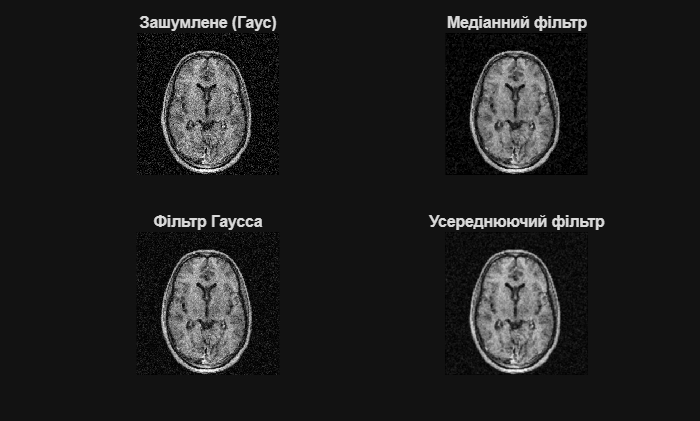

img_gauss = imnoise(best_img, 'gaussian');

f_med = medfilt2(img_gauss);

h_gauss = fspecial('gaussian', [3 3], 0.5);
f_gauss = imfilter(img_gauss, h_gauss);

h_avg = fspecial('average', [3 3]);
f_avg = imfilter(img_gauss, h_avg);

figure('Name', 'Результати фільтрації');
subplot(2,2,1); imshow(img_gauss, []); title('Зашумлене (Гаус)');
subplot(2,2,2); imshow(f_med, []); title('Медіанний фільтр');
subplot(2,2,3); imshow(f_gauss, []); title('Фільтр Гаусса');
subplot(2,2,4); imshow(f_avg, []); title('Усереднюючий фільтр');

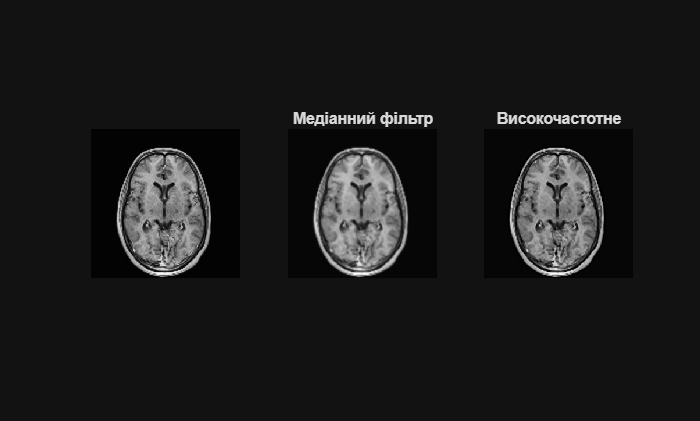


% результат у псевдокольорі

% img_smooth = imgaussfilt(best_img, 0.8); 
img_med = medfilt2(img_smooth, [3 3]);
img_final = imsharpen(img_med, 'Radius', 1, 'Amount', 2);
figure('Name', 'Покращення');

subplot(1,3,1);
imshow(best_img, []);
% title('Гауссівське згладжування');

subplot(1,3,2);
imshow(img_med, []);
title('Медіанний фільтр');

subplot(1,3,3);
imshow(img_final, []);
% colormap(hot); 
% colorbar;
title('Високочастотне');

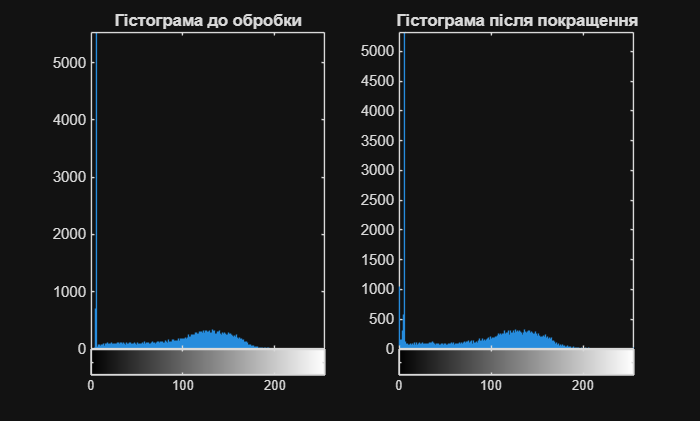


figure('Name', 'Аналіз розподілу яскравості');
subplot(1,2,1); imhist(best_img); title('Гістограма до обробки');
subplot(1,2,2); imhist(img_final); title('Гістограма після покращення');

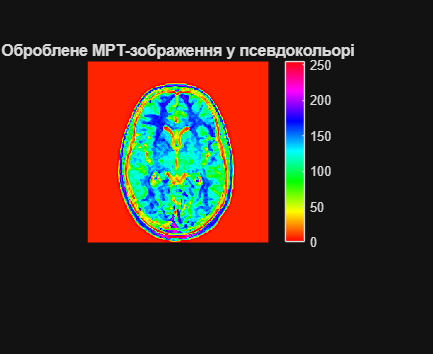

figure('Name', 'Фінальний результат у псевдокольорі');

imshow(img_final, []); 
colormap("hsv"); 
colorbar; 
title('Оброблене МРТ-зображення у псевдокольорі');